**INF6223**

**Devoir 1 - Partie II **

**Par : Pires LUFUNGULA & Traore Mazen Farah**

Lien git pour le projet: **https://github.com/Pira019/tp1_MatLab_2023-3-INF6223-01**

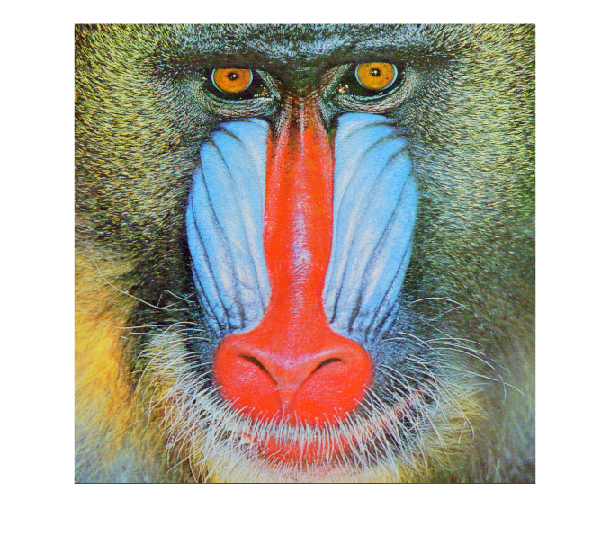

% Initialisation des chemins vers les fichiers

imgBaboonRBG = 'Donnees/BaboonRGB.bmp';
imgPirate =  'Donnees/pirate.tif';
%VidViptraffic = imread('/Données/viptraffic.avi');

%Lectures
imgBaboonRBG_ = imread(imgBaboonRBG);
imgPirate_ = imread(imgPirate);

%afficher les images
imshow(imgBaboonRBG_,[]);

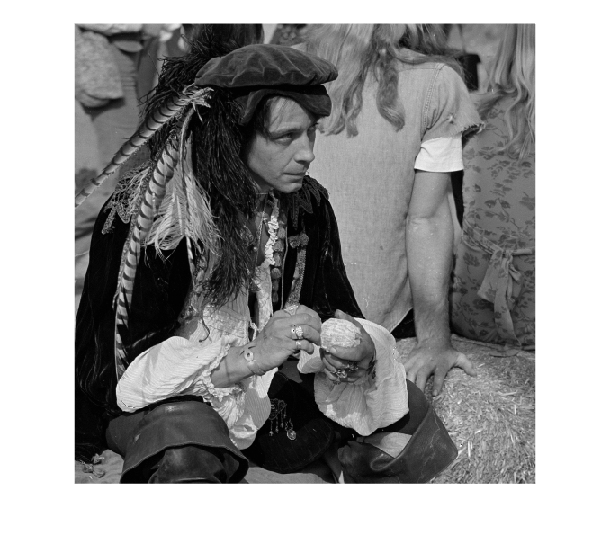

imshow(imgPirate_,[])

%Informations sur les images 
disp('Informations de l''image BaboonRBG:');

Informations de l'image BaboonRBG:


disp(imfinfo(imgBaboonRBG));

              Filename: 'D:\Cours\Uqo\Automne 2023\2023-3-INF6223-01 Systèmes de communications multimédias\DEVOIR 1\tp1_MatLab_2023-3-INF6223-01\DEVOIR1-Partie II\Donnees\BaboonRGB.bmp'
           FileModDate: '04-Oct-2023 13:42:33'
              FileSize: 786486
                Format: 'bmp'
         FormatVersion: 'Version 3 (Microsoft Windows 3.x)'
                 Width: 512
                Height: 512
              BitDepth: 24
             ColorType: 'truecolor'
       FormatSignature: 'BM'
    NumColormapEntries: 0
              Colormap: []
               RedMask: []
             GreenMask: []
              BlueMask: []
       ImageDataOffset: 54
      BitmapHeaderSize: 40
             NumPlanes: 1
       CompressionType: 'none'
            BitmapSize: 786432
        HorzResolution: 0
        VertResolution: 0
         NumColorsUsed: 0
    NumImportantColors: 0



%disp('Informations de l''image Pirate:');
disp(imfinfo(imgPirate));

                       Filename: 'D:\Cours\Uqo\Automne 2023\2023-3-INF6223-01 Systèmes de communications multimédias\DEVOIR 1\tp1_MatLab_2023-3-INF6223-01\DEVOIR1-Partie II\Donnees\pirate.tif'
                    FileModDate: '04-oct.-2023 13:42:33'
                       FileSize: 262750
                         Format: 'tif'
                  FormatVersion: []
                          Width: 512
                         Height: 512
                       BitDepth: 8
                      ColorType: 'grayscale'
                FormatSignature: [73 73 42 0]
                      ByteOrder: 'little-endian'
                 NewSubFileType: 0
                  BitsPerSample: 8
                    Compression: 'Uncompressed'
      PhotometricInterpretation: 'BlackIsZero'
                   StripOffsets: [24 9752 19480 29208 38936 48664 58392 68120 77848 87576 97304 107032 116760 126488 136216 145944 155672 165400 175128 184856 194584 204312 214040 223768 233496 243224 252952]
            

% Obtenir les dimensions des images
disp('Dimensions de l''image BaboonRBG :');

Dimensions de l'image BaboonRBG :


sizeImgBaboonRBG = size(imgBaboonRBG);
disp(sizeImgBaboonRBG);

     1    21



disp('Dimensions de l''image Pirate :');

Dimensions de l'image Pirate :


sizeImgPirate = size(imgPirate);
disp(sizeImgPirate);

     1    18




% Enregistrer des images
imwrite(imgBaboonRBG_, 'Donnees/nouvelle_image_BaboonRBG.bmp');
imwrite(imgPirate_, 'Donnees/nouvelle_image_Pirate.tif');



**R1/ Quelques caractéristiques des deux fichiers **

**Image : BaboonRGB.bmp**

**Dimensions :** 512x512 pixels

**Taille du fichier : **786,486 octets

**Profondeur des couleurs :** 24 bits (Truecolor)

**Format de couleur : **RVB (Rouge, Vert, Bleu)

**Valeur minimale des pixels (par canal) :** 0 (pour le rouge, le vert et le bleu)

**Valeur maximale des pixels (par canal) :** 255 (pour le rouge, le vert et le bleu)

**Image : pirate.tif**

**Dimensions : **512x512 pixels

**Taille du fichier : **262,750 octets

**Profondeur des couleurs : **8 bits (niveaux de gris)

**Format de couleur :** Niveaux de gris (image en niveaux de gris)

**Valeur minimale des pixels :** 0 (noir)

**Valeur maximale des pixels :** 255 (blanc)

**R2/ Dernier pixel de la ligne 100 pour chaque image**

% Obtenir la valeur du dernier pixel de la ligne 100 BaboonRGB.bmp 
disp('La valeur du dernier pixel de la ligne 100 pour BaboonRGB.bmp :');

La valeur du dernier pixel de la ligne 100 pour BaboonRGB.bmp :


disp(imgBaboonRBG_(100, end, :));


(:,:,1) =

   162


(:,:,2) =

   175


(:,:,3) =

   115



Canal Rouge (R) : 162

Canal Vert (G) : 175

Canal Bleu (B) : 115


% Obtenir la valeur du dernier pixel de la ligne 100 de l'image pirate.tif
disp(imgPirate_(100, end));

   153



Ce pixel a une intensité de 153 sur une échelle de 0 (noir) à 255 (blanc) dans ce contexte d'une image en niveaux de gris aussi cette valeur indique une luminosité modérée pour ce pixel particulier.

**R3/ Visualiser chaque composante R, G ou B de l’image ‘’BaboonRGB’’ comme une image monochrome**

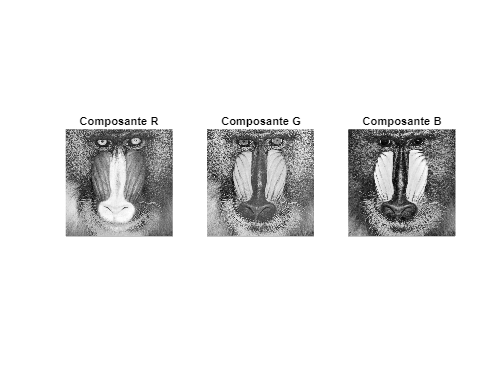

 
% Extraire les composantes R, G et B
composanteR = imgBaboonRBG_(:,:,1);  
composanteG = imgBaboonRBG_(:,:,2);  
composanteB = imgBaboonRBG_(:,:,3); 

figure;

subplot(1, 3, 1);
imshow(composanteR, []);
title('Composante R');

subplot(1, 3, 2);
imshow(composanteG, []);
title('Composante G');

subplot(1, 3, 3);
imshow(composanteB, []);
title('Composante B');

**R4/ Afficher chacune des composantes Y, Cb et Cr comme une image monochrome**

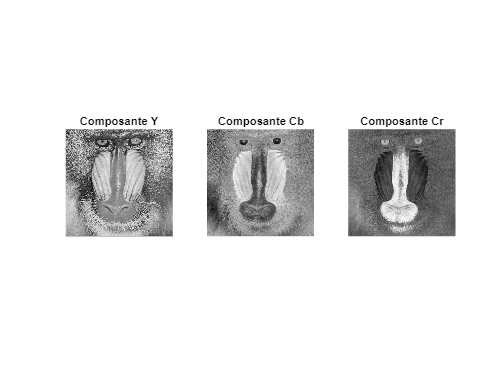

% Convertir l'image RGB en YCbCr
imgYCbCr = rgb2ycbcr(imgBaboonRBG_);

% Extraire les composantes Y, Cb et Cr
composanteY = imgYCbCr(:,:,1);  % Luminance
composanteCb = imgYCbCr(:,:,2);  % Chrominance bleue
composanteCr = imgYCbCr(:,:,3);  % Chrominance rouge

% Afficher chaque composante en tant qu'image monochrome
figure;

subplot(1, 3, 1);
imshow(composanteY, []);
title('Composante Y');

subplot(1, 3, 2);
imshow(composanteCb, []);
title('Composante Cb');

subplot(1, 3, 3);
imshow(composanteCr, []);
title('Composante Cr');

Le constat typique est que la composante Y (luminance) représente l'intensité lumineuse de l'image, tandis que les composantes Cb et Cr représentent les différences de couleur par rapport à la composante de luminance.

**R5\**

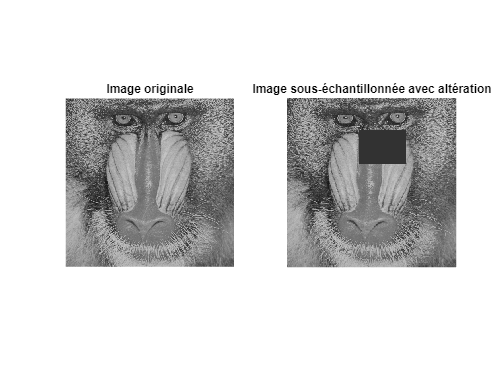

% on a va utiliser l'image monochrome(composanteY) trouvé à question 4

% Sous-échantillonner l'image en réduisant sa résolution par une cadence de 2 selon les deux dimensions
sous_echantillonnee = composanteY(1:2:end, 1:2:end);

sous_echantillonnee(50:100, 110:180) = 50; % % Altérer une la région de 50x50 pixels

% Afficher l'image originale et l'image sous-échantillonnée avec la région altérée
figure;
subplot(1, 2, 1), imshow(composanteY), title('Image originale');
subplot(1, 2, 2), imshow(sous_echantillonnee), title('Image sous-échantillonnée avec altération');

**R6/Sauvegarder l’image sous-échantillonnée et altérée.**


% Sauvegarde de l'image sous-échantillonnée et altérée la variable (sous_echantillonnee)
imwrite(sous_echantillonnee, 'Donnees/imgSousEchantillonneeAlteree.bmp');

**R7/Afficher le spectre d’amplitude de l’image**

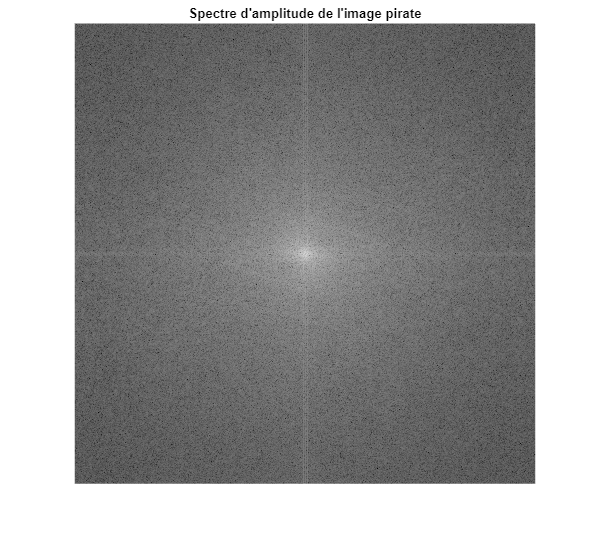

pirateImgFourierTransform = fft2(double(imgPirate_));

ImgPirateCentre = fftshift(pirateImgFourierTransform); % % Centrer le spectre 

ampl = abs(ImgPirateCentre);

% Visualiser le spectre d'amplitude
figure;
imshow(log(1 + ampl), []);
title('Spectre d''amplitude de l''image pirate');

**R8/ Exploration faite avec ****doc**** pour les vidéos**